# TEST 1 VC

1) exponencial (1-exp(-kx)) centrada en la imatge i correctament dimensionada de tal forma que pràcticament ocupi tota la imatge. Mostreu codi i una figura amb la imatge resultant.

x = linspace(0,400,400);
y = linspace(0,400,400)';
dist = sqrt((x-200).^2 + (y-200).^2)

dist =   282.8427  282.1347  281.4285  280.7241  280.0216  279.3208  278.6219  277.9249  277.2297  276.5364  275.8450  275.1556  274.4680  273.7824  273.0988  272.4171  271.7375  271.0598  270.3841  269.7105  269.0390  268.3694  267.7020  267.0367  266.3735  265.7124  265.0534  264.3967  263.7420  263.0896  262.4394  261.7914  261.1457  260.5022  259.8610  259.2220  258.5854  257.9511  257.3192  256.6896  256.0624  255.4375  254.8151  254.1951  253.5776  252.9625  252.3500  251.7399  251.1323  250.5273
  282.1347  281.4250  280.7170  280.0108  279.3064  278.6039  277.9032  277.2043  276.5073  275.8122  275.1190  274.4277  273.7384  273.0509  272.3655  271.6820  271.0005  270.3209  269.6434  268.9680  268.2945  267.6232  266.9539  266.2867  265.6216  264.9586  264.2978  263.6391  262.9826  262.3283  261.6762  261.0263  260.3787  259.7333  259.0902  258.4493  257.8108  257.1746  256.5407  255.9092  255.2801  254.6534  254.0290  253.4071  252.7877  252.1707  251.5562  250.9442  250.3347  

POU = exp(dist/150)

POU =     6.5904    6.5594    6.5286    6.4980    6.4676    6.4375    6.4076    6.3779    6.3484    6.3191    6.2900    6.2612    6.2326    6.2041    6.1759    6.1479    6.1201    6.0925    6.0652    6.0380    6.0110    5.9842    5.9577    5.9313    5.9051    5.8792    5.8534    5.8278    5.8025    5.7773    5.7523    5.7275    5.7029    5.6785    5.6542    5.6302    5.6064    5.5827    5.5592    5.5360    5.5129    5.4899    5.4672    5.4447    5.4223    5.4001    5.3781    5.3563    5.3346    5.3131
    6.5594    6.5284    6.4977    6.4672    6.4369    6.4068    6.3769    6.3473    6.3179    6.2887    6.2597    6.2309    6.2023    6.1740    6.1458    6.1179    6.0901    6.0626    6.0353    6.0082    5.9813    5.9545    5.9280    5.9017    5.8756    5.8497    5.8240    5.7985    5.7731    5.7480    5.7231    5.6983    5.6738    5.6494    5.6253    5.6013    5.5775    5.5539    5.5305    5.5072    5.4842    5.4613    5.4386    5.4161    5.3938    5.3717    5.3497    5.3279    5.3063   

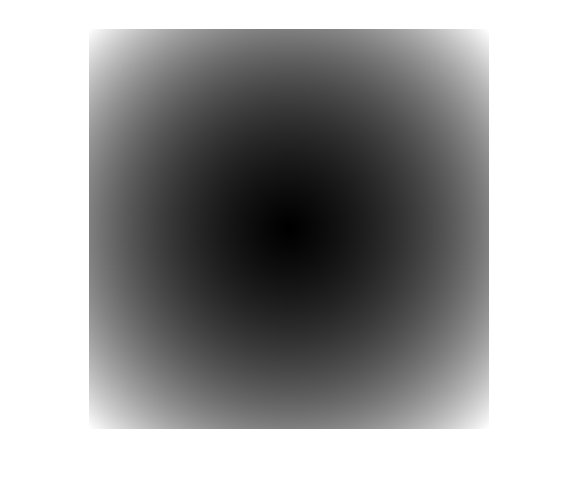

imshow(POU,[]);

2) Utilitzant Sobel, Calculeu l’angle del gradient en graus per a cada píxel de la imatge S. Mostreu codi i una figura amb la imatge resultant O.

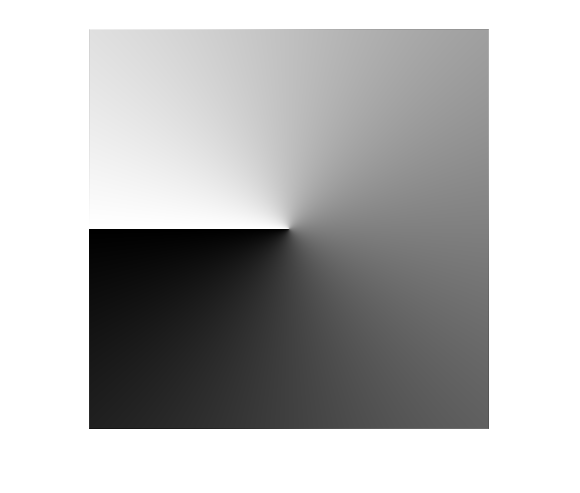

[Gangle, O] = imgradient(POU,'sobel');
imshow(O,[])

3) Utilitzant un codi propi calculeu l’histograma H de la imatge O utilitzant 360 bins o divisions. Mostreu codi i una figura amb el plot (bar) resultant de H.

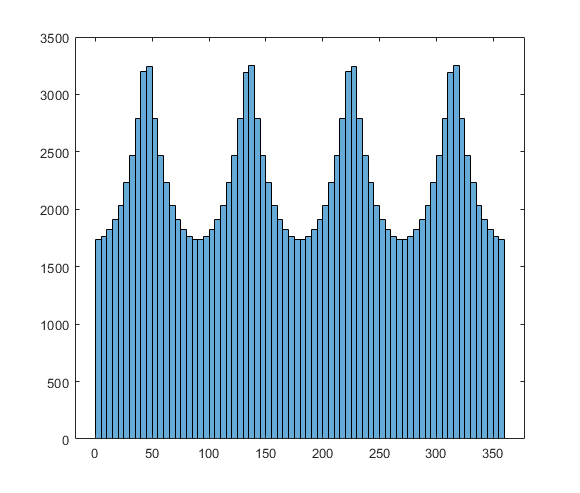

%% O esta originalment entre -179 i 180

O = O+180;
histogram(O)

%% O esta originalment entre -179 i 180
H = [linspace(1,360,360);zeros(360,1)']

H =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


max(max(O))

ans = 359.8557

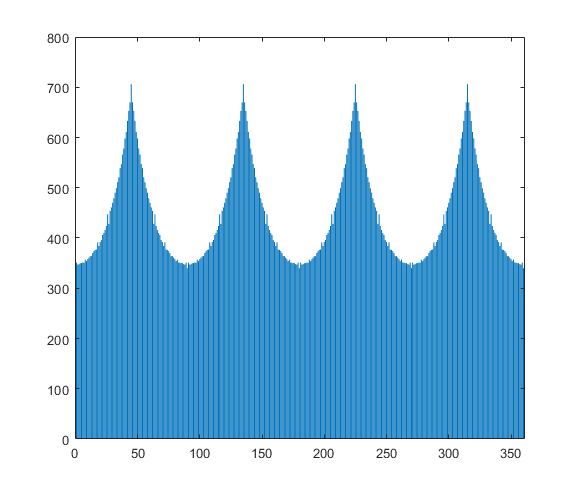

for i = 1:400
    for j = 1:400
        angle = round(O(i,j));
        if (angle == 0)
            angle = 360;
        end
        H(2,angle) = H(2,angle)+ 1;
    end
end
bar(H(1,:),H(2,:))

4) Marqueu amb color verd intens els píxels de la imatge S que tinguin un mòdul del gradient més elevat. Mostreu codi i una figura amb la imatge resultant en una imatge RGB.

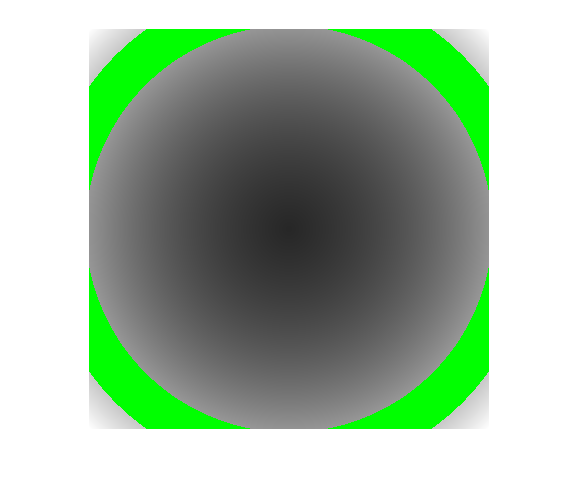

POU = uint8(POU*255/max(max(POU)));
POUg=POU;
POUo = POUg;
POUg(POUg> 150 & POUg < 200) = 255;
POUo(POUo> 150 & POUo < 200) = 0;
POUrgb = cat(3, POUo, POUg,POUo);
imshow(POUrgb)